# ASTR HW 7 

## PROBLEM 1

clear all
close all 
clc
afile = readmatrix("ssp_datav3.csv");
% Assigning the variables 
r_a = afile(:,1);  % Aphelion [km]
r_p = afile(:,2);  % Perihelion [km]
M_planets = afile(:,4);  % Mass of planets [kg]
v_a = afile(:, 7);   % Velocity at aphelion [km/s]
v_p = afile(:, 8);  % Velocity at perhelion [km/s]
v_esc = afile(:, 10);  % Escape velocity [km/s]
M_sun = [1.989*10^30 1.989*10^30 1.989*10^30 1.989*10^30 M_planets(1)];  % Mass of Sun [kg]
m_i = [10 100 1000].^3*4*pi/3*3.3/1000*10^6;  % Mass of impactor [kg]
G = 6.67*10^(-20);  % Graviational constant [km^3/kg/s^2]


## Condition 1 : At Aphelion 

% Earth 
[v_E1_1, prob_E1_1] = cal_object_vel(M_planets(1), m_i(1),v_a(1),v_esc(1));  % 10m impactor
[v_E1_2, prob_E1_2] = cal_object_vel(M_planets(1), m_i(2),v_a(1),v_esc(1));  % 100m impactor
[v_E1_3, prob_E1_3] = cal_object_vel(M_planets(1), m_i(3),v_a(1),v_esc(1));  % 1000m impactor
% Mars
[v_M1_1, prob_M1_1] = cal_object_vel(M_planets(2), m_i(1),v_a(2),v_esc(2));  % 10m impactor
[v_M1_2, prob_M1_2] = cal_object_vel(M_planets(2), m_i(2),v_a(2),v_esc(2));  % 100m impactor
[v_M1_3, prob_M1_3] = cal_object_vel(M_planets(2), m_i(3),v_a(2),v_esc(2));  % 1000m impactor
% Jupiter
[v_J1_1, prob_J1_1] = cal_object_vel(M_planets(3), m_i(1),v_a(3),v_esc(3));  % 10m impactor
[v_J1_2, prob_J1_2] = cal_object_vel(M_planets(3), m_i(2),v_a(3),v_esc(3));  % 100m impactor
[v_J1_3, prob_J1_3] = cal_object_vel(M_planets(3), m_i(3),v_a(3),v_esc(3));  % 1000m impactor
% Saturn
[v_S1_1, prob_S1_1] = cal_object_vel(M_planets(4), m_i(1),v_a(4),v_esc(4));  % 10m impactor
[v_S1_2, prob_S1_2] = cal_object_vel(M_planets(4), m_i(2),v_a(4),v_esc(4));  % 100m impactor
[v_S1_3, prob_S1_3] = cal_object_vel(M_planets(4), m_i(3),v_a(4),v_esc(4));  % 1000m impactor
% Moon 
[v_Mo1_1, prob_Mo1_1] = cal_object_vel(M_planets(5), m_i(1),v_a(5),v_esc(5));  % 10m impactor
[v_Mo1_2, prob_Mo1_2] = cal_object_vel(M_planets(5), m_i(2),v_a(5),v_esc(5));  % 100m impactor
[v_Mo1_3, prob_Mo1_3] = cal_object_vel(M_planets(5), m_i(3),v_a(5),v_esc(5));  % 1000m impactor

## Condition 2: At Perihelion

% Earth 
[v_E2_1, prob_E2_1] = cal_object_vel(M_planets(1), m_i(1),v_p(1),v_esc(1));  % 10m impactor
[v_E2_2, prob_E2_2] = cal_object_vel(M_planets(1), m_i(2),v_p(1),v_esc(1));  % 100m impactor
[v_E2_3, prob_E2_3] = cal_object_vel(M_planets(1), m_i(3),v_p(1),v_esc(1));  % 1000m impactor
% Mars
[v_M2_1, prob_M2_1] = cal_object_vel(M_planets(2), m_i(1),v_p(2),v_esc(2));  % 10m impactor
[v_M2_2, prob_M2_2] = cal_object_vel(M_planets(2), m_i(2),v_p(2),v_esc(2));  % 100m impactor
[v_M2_3, prob_M2_3] = cal_object_vel(M_planets(2), m_i(3),v_p(2),v_esc(2));  % 1000m impactor
% Jupiter
[v_J2_1, prob_J2_1] = cal_object_vel(M_planets(3), m_i(1),v_p(3),v_esc(3));  % 10m impactor
[v_J2_2, prob_J2_2] = cal_object_vel(M_planets(3), m_i(2),v_p(3),v_esc(3));  % 100m impactor
[v_J2_3, prob_J2_3] = cal_object_vel(M_planets(3), m_i(3),v_p(3),v_esc(3));  % 1000m impactor
% Saturn
[v_S2_1, prob_S2_1] = cal_object_vel(M_planets(4), m_i(1),v_p(4),v_esc(4));  % 10m impactor
[v_S2_2, prob_S2_2] = cal_object_vel(M_planets(4), m_i(2),v_p(4),v_esc(4));  % 100m impactor
[v_S2_3, prob_S2_3] = cal_object_vel(M_planets(4), m_i(3),v_p(4),v_esc(4));  % 1000m impactor
% Moon 
[v_Mo2_1, prob_Mo2_1] = cal_object_vel(M_planets(5), m_i(1),v_p(5),v_esc(5));  % 10m impactor
[v_Mo2_2, prob_Mo2_2] = cal_object_vel(M_planets(5), m_i(2),v_p(5),v_esc(5));  % 100m impactor
[v_Mo2_3, prob_Mo2_3] = cal_object_vel(M_planets(5), m_i(3),v_p(5),v_esc(5));  % 1000m impactor

## Total Probability: (both aphelion and perhelion together)

% Earth
prob_E_tot1 = prob_E1_1*prob_E2_1;  % Impactor 10m
prob_E_tot2 = prob_E1_2*prob_E2_2;  % Impactor 100m
prob_E_tot3 = prob_E1_3*prob_E2_3;  % Impactor 1000m
prob_E = [prob_E_tot1, prob_E_tot2, prob_E_tot3];
% Mars
prob_M_tot1 = prob_M1_1*prob_M2_1;  % Impactor 10m
prob_M_tot2 = prob_M1_2*prob_M2_2;  % Impactor 100m
prob_M_tot3 = prob_M1_3*prob_M2_3;  % Impactor 1000m
prob_M = [prob_M_tot1, prob_M_tot2, prob_M_tot3];
% Jupiter
prob_J_tot1 = prob_J1_1*prob_J2_1;  % Impactor 10m
prob_J_tot2 = prob_J1_2*prob_J2_2;  % Impactor 100m
prob_J_tot3 = prob_J1_3*prob_J2_3;  % Impactor 1000m
prob_J = [prob_J_tot1, prob_J_tot2, prob_J_tot3];
% Saturn
prob_S_tot1 = prob_S1_1*prob_S2_1;  % Impactor 10m
prob_S_tot2 = prob_S1_2*prob_S2_2;  % Impactor 100m
prob_S_tot3 = prob_S1_3*prob_S2_3;  % Impactor 1000m
prob_s = [prob_S_tot1, prob_S_tot2, prob_S_tot3];
% Moon 
prob_Mo_tot1 = prob_Mo1_1*prob_Mo2_1;  % Impactor 10m
prob_Mo_tot2 = prob_Mo1_2*prob_Mo2_2;  % Impactor 100m
prob_Mo_tot3 = prob_Mo1_3*prob_Mo2_3;  % Impactor 1000m
prob_Mo = [prob_Mo_tot1, prob_Mo_tot2, prob_Mo_tot3];

## Plotting

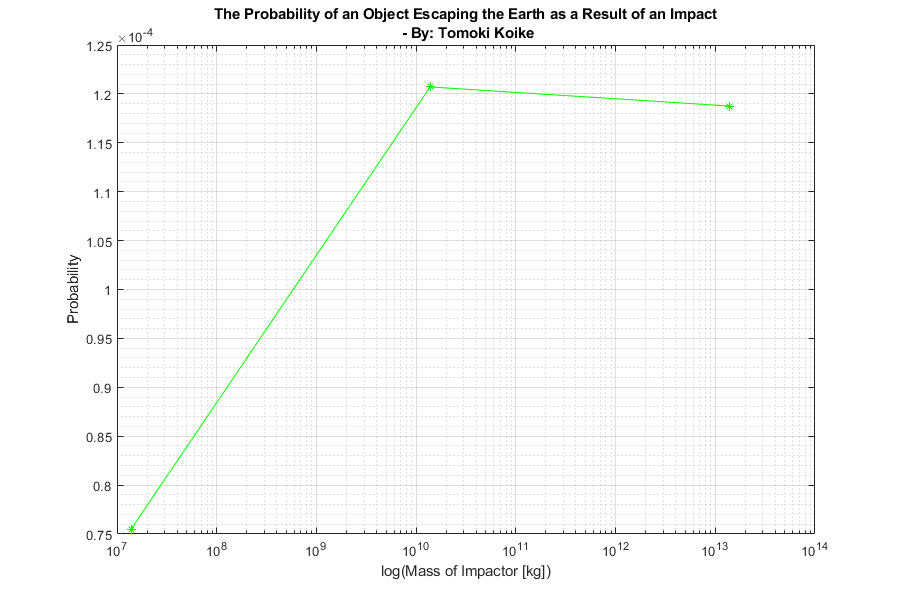

% Earth
figure('Renderer', 'painters', 'Position', [10 10 900 600]);
semilogx(m_i, prob_E, '*-g')
title({['The Probability of an Object Escaping the Earth as a Result of an ' ...
    'Impact'],' - By: Tomoki Koike'})
xlabel('log(Mass of Impactor [kg])')
ylabel('Probability')
grid on
grid minor
box on

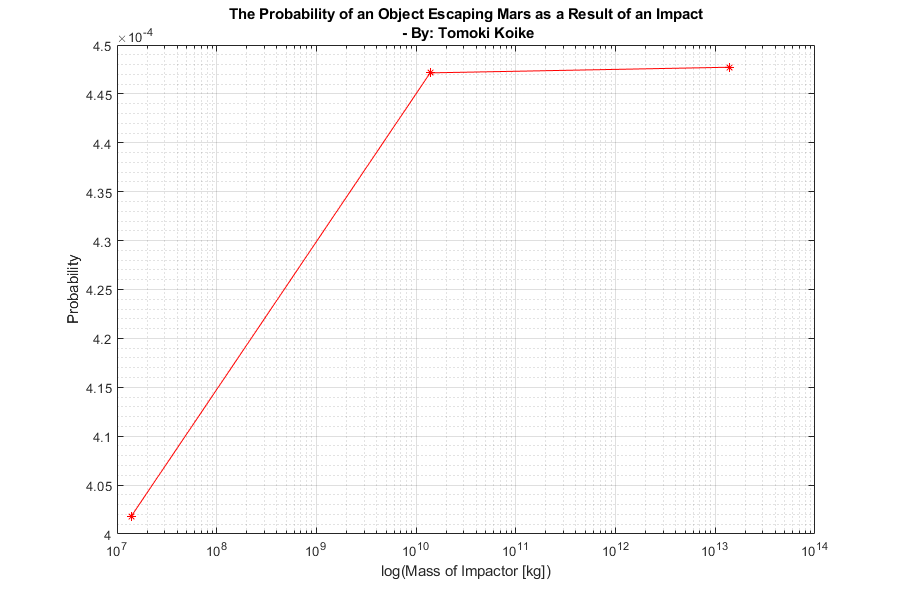

% Mars
figure('Renderer', 'painters', 'Position', [10 10 900 600]);
semilogx(m_i, prob_M, '*-r')
title({['The Probability of an Object Escaping Mars as a Result of an ' ...
    'Impact'],' - By: Tomoki Koike'})
xlabel('log(Mass of Impactor [kg])')
ylabel('Probability')
grid on
grid minor
box on

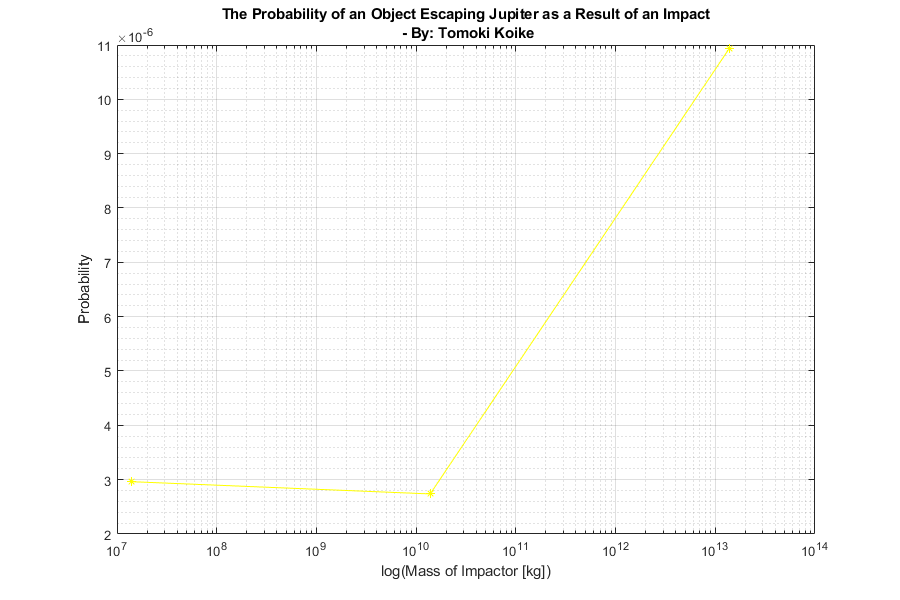

% Jupiter
figure('Renderer', 'painters', 'Position', [10 10 900 600]);
semilogx(m_i, prob_J, '*-y')
title({['The Probability of an Object Escaping Jupiter as a Result of an ' ...
    'Impact'],' - By: Tomoki Koike'})
xlabel('log(Mass of Impactor [kg])')
ylabel('Probability')
grid on
grid minor
box on

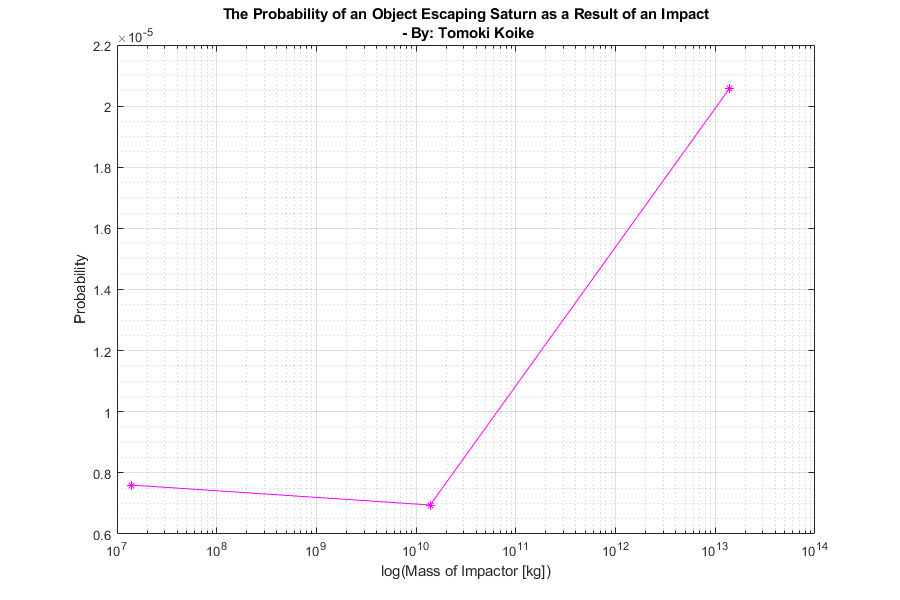

% Saturn
figure('Renderer', 'painters', 'Position', [10 10 900 600]);
semilogx(m_i, prob_s, '*-m')
title({['The Probability of an Object Escaping Saturn as a Result of an ' ...
    'Impact'],' - By: Tomoki Koike'})
xlabel('log(Mass of Impactor [kg])')
ylabel('Probability')
grid on
grid minor
box on

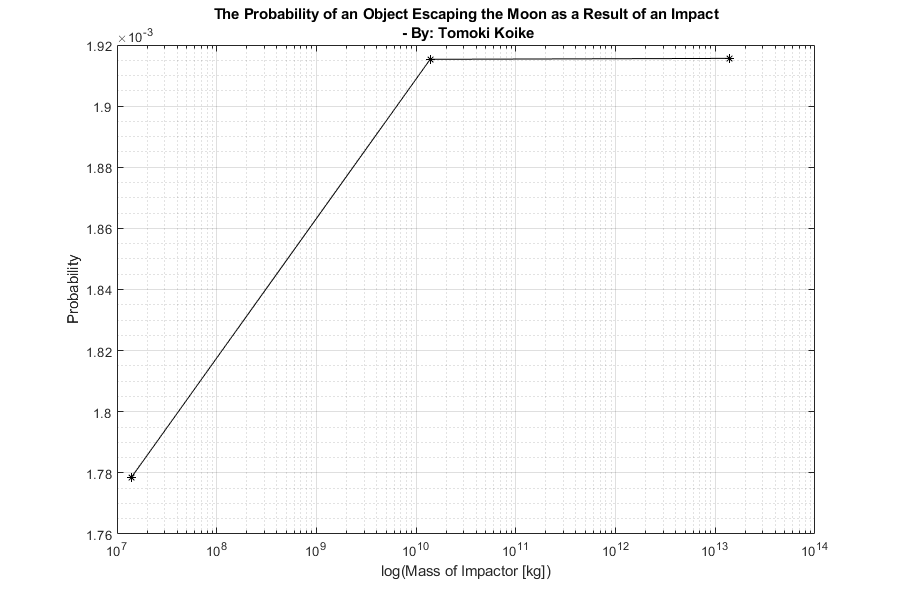

% Moon
figure('Renderer', 'painters', 'Position', [10 10 900 600]);
semilogx(m_i, prob_Mo, '*-k')
title({['The Probability of an Object Escaping the Moon as a Result of an ' ...
    'Impact'],' - By: Tomoki Koike'})
xlabel('log(Mass of Impactor [kg])')
ylabel('Probability')
grid on
grid minor
box on

## Kinetic Energy: Plotting

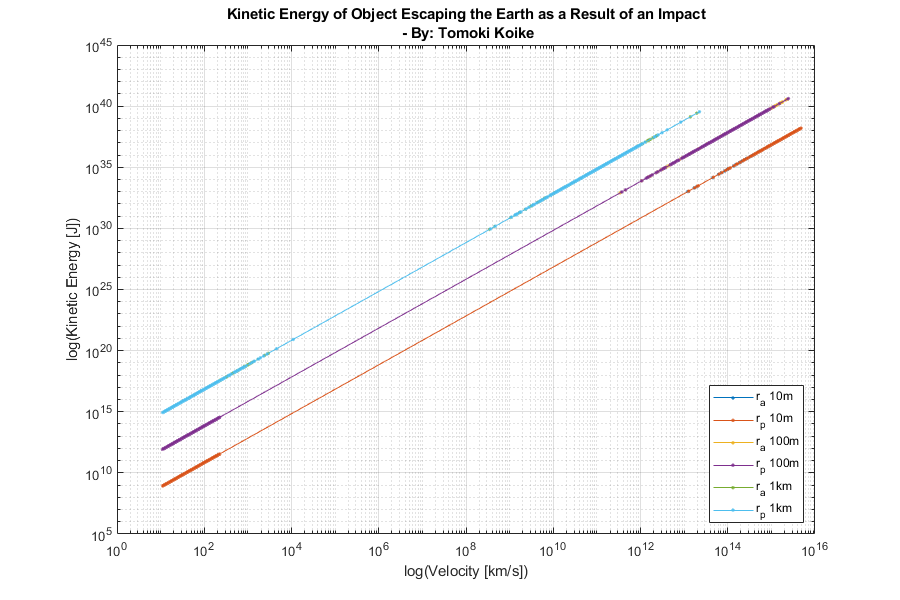

% Earth
figure('Renderer', 'painters', 'Position', [10 10 900 600]);
loglog(sort(v_E1_1), cal_KE(sort(v_E1_1), m_i(1)), '.-')
title({['Kinetic Energy of Object Escaping the Earth as a Result of an ' ...
    'Impact'],' - By: Tomoki Koike'})
xlabel('log(Velocity [km/s])')
ylabel('log(Kinetic Energy [J])')
hold on 
loglog(sort(v_E2_1), cal_KE(sort(v_E2_1), m_i(1)), '.-')
loglog(sort(v_E1_2), cal_KE(sort(v_E1_2), m_i(2)), '.-')
loglog(sort(v_E2_2), cal_KE(sort(v_E2_2), m_i(2)), '.-')
loglog(sort(v_E1_3), cal_KE(sort(v_E1_3), m_i(3)), '.-')
loglog(sort(v_E2_3), cal_KE(sort(v_E2_3), m_i(3)), '.-')
hold off
legend('r_a 10m', 'r_p 10m', 'r_a 100m', 'r_p 100m', 'r_a 1km', 'r_p 1km', ...
    'Location', 'southeast')
grid on
grid minor
box on

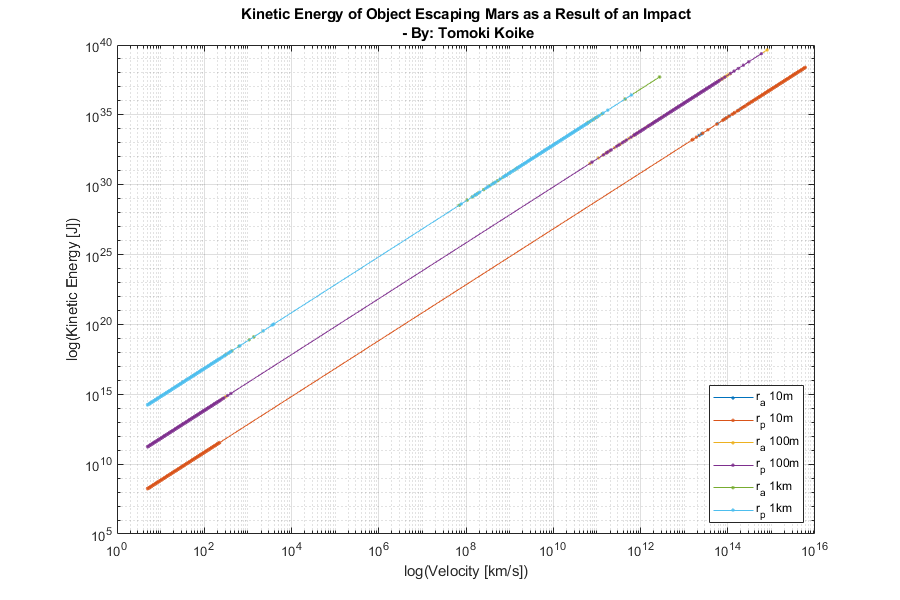

% Mars
figure('Renderer', 'painters', 'Position', [10 10 900 600]);
loglog(sort(v_M1_1), cal_KE(sort(v_M1_1), m_i(1)), '.-')
title({['Kinetic Energy of Object Escaping Mars as a Result of an ' ...
    'Impact'],' - By: Tomoki Koike'})
xlabel('log(Velocity [km/s])')
ylabel('log(Kinetic Energy [J])')
hold on 
loglog(sort(v_M2_1), cal_KE(sort(v_M2_1), m_i(1)), '.-')
loglog(sort(v_M1_2), cal_KE(sort(v_M1_2), m_i(2)), '.-')
loglog(sort(v_M2_2), cal_KE(sort(v_M2_2), m_i(2)), '.-')
loglog(sort(v_M1_3), cal_KE(sort(v_M1_3), m_i(3)), '.-')
loglog(sort(v_M2_3), cal_KE(sort(v_M2_3), m_i(3)), '.-')
hold off
legend('r_a 10m', 'r_p 10m', 'r_a 100m', 'r_p 100m', 'r_a 1km', 'r_p 1km', ...
    'Location', 'southeast')
grid on
grid minor
box on

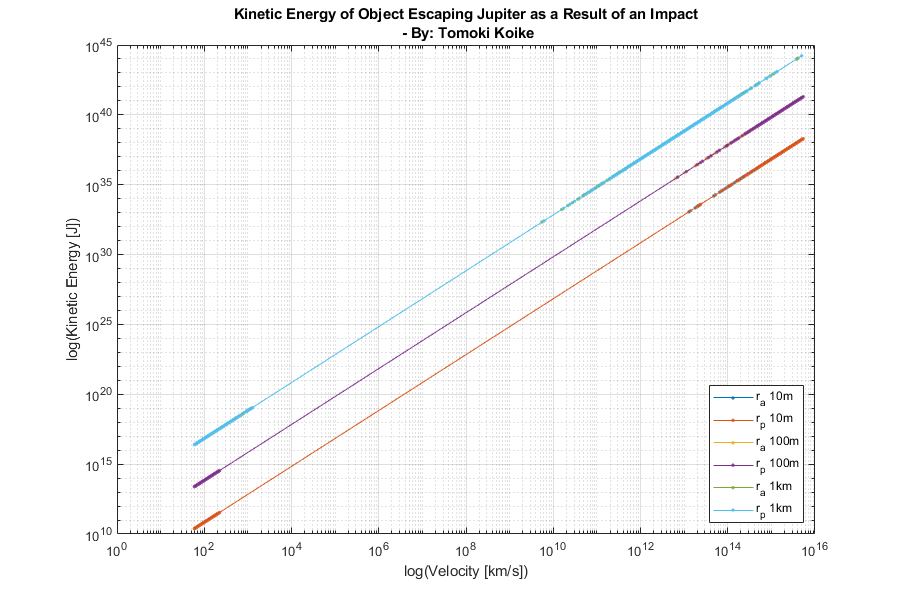

% Jupiter
figure('Renderer', 'painters', 'Position', [10 10 900 600]);
loglog(sort(v_J1_1), cal_KE(sort(v_J1_1), m_i(1)), '.-')
title({['Kinetic Energy of Object Escaping Jupiter as a Result of an ' ...
    'Impact'],' - By: Tomoki Koike'})
xlabel('log(Velocity [km/s])')
ylabel('log(Kinetic Energy [J])')
hold on 
loglog(sort(v_J2_1), cal_KE(sort(v_J2_1), m_i(1)), '.-')
loglog(sort(v_J1_2), cal_KE(sort(v_J1_2), m_i(2)), '.-')
loglog(sort(v_J2_2), cal_KE(sort(v_J2_2), m_i(2)), '.-')
loglog(sort(v_J1_3), cal_KE(sort(v_J1_3), m_i(3)), '.-')
loglog(sort(v_J2_3), cal_KE(sort(v_J2_3), m_i(3)), '.-')
hold off
legend('r_a 10m', 'r_p 10m', 'r_a 100m', 'r_p 100m', 'r_a 1km', 'r_p 1km', ...
    'Location', 'southeast')
grid on
grid minor
box on

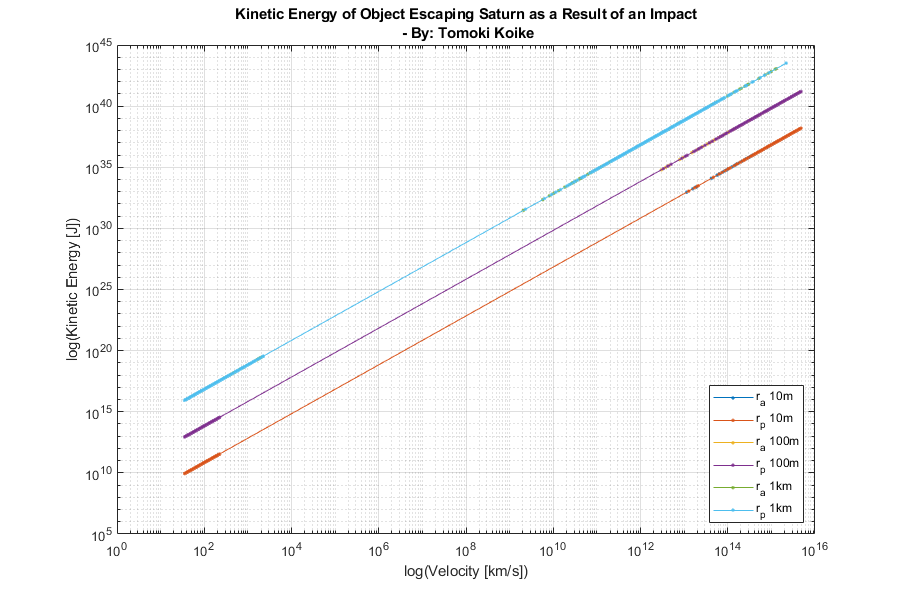

% Saturn
figure('Renderer', 'painters', 'Position', [10 10 900 600]);
loglog(sort(v_S1_1), cal_KE(sort(v_S1_1), m_i(1)), '.-')
title({['Kinetic Energy of Object Escaping Saturn as a Result of an ' ...
    'Impact'],' - By: Tomoki Koike'})
xlabel('log(Velocity [km/s])')
ylabel('log(Kinetic Energy [J])')
hold on 
loglog(sort(v_S2_1), cal_KE(sort(v_S2_1), m_i(1)), '.-')
loglog(sort(v_S1_2), cal_KE(sort(v_S1_2), m_i(2)), '.-')
loglog(sort(v_S2_2), cal_KE(sort(v_S2_2), m_i(2)), '.-')
loglog(sort(v_S1_3), cal_KE(sort(v_S1_3), m_i(3)), '.-')
loglog(sort(v_S2_3), cal_KE(sort(v_S2_3), m_i(3)), '.-')
hold off
legend('r_a 10m', 'r_p 10m', 'r_a 100m', 'r_p 100m', 'r_a 1km', 'r_p 1km', ...
    'Location', 'southeast')
grid on
grid minor
box on

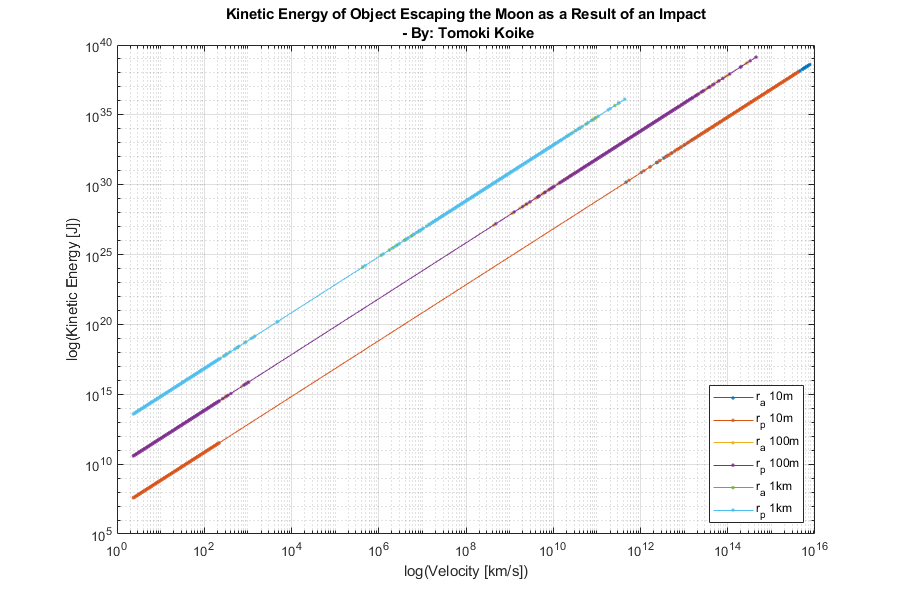

% Moon
figure('Renderer', 'painters', 'Position', [10 10 900 600]);
loglog(sort(v_Mo1_1), cal_KE(sort(v_Mo1_1), m_i(1)), '.-')
title({['Kinetic Energy of Object Escaping the Moon as a Result of an ' ...
    'Impact'],' - By: Tomoki Koike'})
xlabel('log(Velocity [km/s])')
ylabel('log(Kinetic Energy [J])')
hold on 
loglog(sort(v_Mo2_1), cal_KE(sort(v_Mo2_1), m_i(1)), '.-')
loglog(sort(v_Mo1_2), cal_KE(sort(v_Mo1_2), m_i(2)), '.-')
loglog(sort(v_Mo2_2), cal_KE(sort(v_Mo2_2), m_i(2)), '.-')
loglog(sort(v_Mo1_3), cal_KE(sort(v_Mo1_3), m_i(3)), '.-')
loglog(sort(v_Mo2_3), cal_KE(sort(v_Mo2_3), m_i(3)), '.-')
hold off
legend('r_a 10m', 'r_p 10m', 'r_a 100m', 'r_p 100m', 'r_a 1km', 'r_p 1km', ...
    'Location', 'southeast')
grid on
grid minor
box on

function m_o = cal_m_o(M, m_i, V, v_esc, beta, gamma, delta)
    m_o = ((M+m_i)*V*(cos(delta)+sin(delta)*tan(gamma)) - ...
        m_i*v_esc*(cos(beta)+sin(beta)*tan(gamma)) - M*V) / ...
        (V*(cos(delta)+sin(delta)*tan(gamma)));
end

function [v_suf, prob] = cal_object_vel(M, m_i, V, v_e)
    v = zeros([181, 181, 21]);
    for beta = 0:180
        for gamma = 0:180
            for delta = 0:20
                m_o = cal_m_o(M, m_i, V, v_e, beta, gamma, delta);
                temp = ((M-m_o+m_i)*sin(delta) - m_i*v_e*sin(beta))/m_o*cos(beta);
                if temp ~= inf
                    v(beta+1, gamma+1, delta+1) = temp;
                end
            end
        end
    end
    v_temp = v(~(isnan(v)|isinf(v)));
    v_num = length(v_temp);
    v_suf = v_temp(v_temp>=v_e);
    v_suf = sort(v_suf);
    v_suf_num = length(v_suf);
    prob = v_suf_num / v_num;
end

function KE = cal_KE(v, m)
    KE = 0.5*m*v.^2;
end